## Import BIDS dataset

**Run 'eeglab' from the folder containing the eeglab codes. This will add all the relevant EEGLAB functions and directories to path.**

eeglab: options file is ~/eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "bids-matlab-tools" v6.1 (see >> help eegplugin_bids)
EEGLAB: adding "bids-validator" v1.1 (see >> help eegplugin_bidsvalidator)
EEGLAB: adding "clean_rawdata" v2.6 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v4.3 (see >> help eegplugin_dipfit)
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


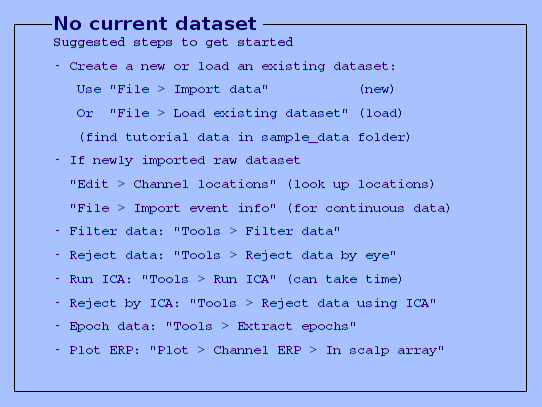

You are using the latest version of EEGLAB.


eeglab

**Steps:**

Select the BIDS folder to work on

BIDS_path = uigetdir(pwd,'Select BIDS dataset folder')

BIDS_path = '/home/user1/Documents/Manisha/eeglab-develop-2022/eeglab/BIDS/ds003969'

Add the folder and subfolders to path. Make the selected BIDS folder to current directory.

addpath(genpath(BIDS_path))

current_path = pwd;
if strcmp(current_path,BIDS_path)==0
    disp('Changing current directory to BIDS dataset folder')
    cd(BIDS_path)
end
[~,dataset_name,~] = fileparts(BIDS_path) 

dataset_name = 'ds003969'

**Test whether the BIDS dataset has a participants.tsv and whether it is empty**

if ~isfile('participants.tsv')
    error('Cannot find participants.tsv')
end

d = dir;
% if a directory is empty, it will contain only '.' and '..'
if (isfolder(BIDS_path)==0) || (length(d)==2) 
    error(['Cannot find ' dataset_name ' BIDS dataset, download it from OpenNeuro.org, uncompress it'])
end

if ~isfolder(fullfile([BIDS_path, '/sub-001/eeg']))
    error(['Cannot find subject and eeg subfolder in the BIDS dataset, download it from OpenNeuro.org, uncompress it'])
    
end

The function pop_importbids() imports a BIDS format folder structure into an EEGLAB study. 

If 'bidsevent' is 'on' then events will be imported from the BIDS .tsv event file and events in the raw binary EEG files will be ignored. Similarly 'bidschanloc', 'on' will import channel locations from BIDS .tsv file and ignore any locations in raw EEG files. The 'studyName' field lets you specify the name of the newly created STUDY.

[STUDY, ALLEEG, opt] = pop_importbids(BIDS_path,'bidsevent','off','bidschanloc','off','studyName',dataset_name);

Importing file: /home/user1/Documents/Manisha/eeglab-develop-2022/eeglab/BIDS/ds003969/sub-001/eeg/sub-001_task-med1breath_eeg.bdf
Reading data in BDF format...
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Importing data events...
eeg_checkset note: creating the original event table (EEG.urevent)
readlocs(): 'elc' format assumed from file extension
Reading file (lines): 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150 160 170 180 190 200 210 220 230 240 250 260 270 280 290 300 310 320 330 340 350 360 370 380 390 400 410 420 430 440 450 460 470 480 490 500 510 520 530 540 550 560 570 580 590 600 610 620 630 640 650 660 670 680 690 700 702
Channel lookup: no location for EXG1,EXG2,EXG3,EXG4,EXG5,EXG6,EXG7,EXG8,GSR1,GSR2,Erg1,Erg2,Resp,Plet,Temp
Send us standard location for your channels at eeglab@sccn.ucsd.edu
Note for expert users: Nose direction is now set from '+Y' to default +X in EEG.chanlocs
Saving dataset...
Importing file: /home

**Check whether an events.json file exists or not. Epoch generation will depend on this.**

% filePattern = fullfile(BIDS_path, '*_events.json'); 
% 
% json_files = dir(filePattern);
% if isempty(json_files)
%     disp('No events file detected. Regular 2s epochs will be generated')
%     event_file = 0;
% else
%     disp('Events file detected! Epochs will be generated with [-0.5, 1.5]s time window ')
%     event_file = 1;
% end

## Process dataset

Loop across datasets and process data epochs. The type of epoch and any other interesting field is in epoch_type.datasetinfo.trialinfo; all fields in this structure will be saved as different columns. Pass a label filename which will be updated by bids2mat.

aws_path = ['s3://openneuro.org/' dataset_name];
label_file = [dataset_name '_labels_s3.txt'];

CURRENTSTUDY = 1;
for CURRENTSET = 1:length(ALLEEG)
    CURRENTSET
    EEG =  ALLEEG(CURRENTSET);
    if event_file == 1
        EEG = pop_epoch(EEG, unique({EEG.event.type}), [-0.5 1.5]);
    else
        EEG = eeg_regepochs(EEG, 'limits', [0 2], 'recurrence', 2);
    end
    bids2mat(EEG,label_file,aws_path)
end

BIDS_DL plugin

pop_bids_dl(STUDY, ALLEEG) % for ds003061

pop_bids_dl(STUDY, ALLEEG) % for ds003969

CURRENTSET = 1

No events file detected. Regular 2s epochs will be generated
The input dataset will be split into 303 epochs of 2 s
Inserting 303 type 'X' events: .......................................40
.......................................80..............................
.........120.......................................160....................
...................200.......................................240..........
.............................280.......................
Sorting the event table.
Splitting the data into 303 2.00-s epochs
pop_epoch():303 epochs selected
Epoching...
pop_epoch():303 epochs generated
pop_epoch(): checking epochs for data discontinuity


eeg_dir = 'mat_files/sub-001/eeg'

Conversion to double from cell is not possible.

Error in bids2mat (line 69)
          [~,Z_12(:,:,i),~,~,~] = arrayfun(@(i)topoplot_DaSh_v2(data(:,i)',EEG.chanlocs,  'chaninfo', EEG.chaninfo), num_timestamps, 'UniformOutput', false)

Error in pop_bids_dl (line 118)
    bids2m